# TRAJECTORIEs

In this file, we explain how special solutions are computed in XPPAUT [1] and where they are stored in the AUTORePO structure. These concepts will be illustrated by using these special trajectories to perform averaging theory on the Chay and Keizer model [2]. The model is the following,

$\begin{array}{l}
c_m \;\dot{\;v} =-\left(I_K +I_{\textrm{Ca}} +I_{K\left(\textrm{Ca}\right)} +I_{K\left(\textrm{ATP}\right)} \right),\\
\;\;\;\;\;\;\dot{n} =\left(n_{\infty \;} -n\right)\tau_n^{-1} ,\\
\;\;\;\;\;\;\dot{c} =-\left(\alpha I_{\textrm{Ca}} +k_{\textrm{PMCA}} c\right)\ldotp 
\end{array}$ (1)

The variable $v$ is the transmembrane potential, $n$ represents the potassium activation variable and finally $c$ the intracellular calcium concentration. The variables $v$ and $n$ are faster than $c$. Therefore, we will refer to the first two ODEs of the previous model as the fast-subsystem.

$\begin{array}{l}
c_m \;\dot{\;v} =-\left(I_K +I_{\textrm{Ca}} +I_{K\left(\textrm{Ca}\right)} +I_{K\left(\textrm{ATP}\right)} \right),\\
\;\;\;\;\;\;\dot{n} =\left(n_{\infty \;} -n\right)\tau_n^{-1} \ldotp 
\end{array}$ (2)

We will compute the 1P-BD of the fast subsystem (2) by using as bifurcation parameter the intracellular calcium concentration $c$. The results will be used to perform averaging theory. For more details regarding the model's dynamical properties the reader is adiviced to refer at [2]. 

[1] Ermentrout B. *Simulating, Analyzing, and Animating Dynamical Systems: A Guide to XPPAUT for Researchers and Students. *SIAM, 2002.

[2] Chay TR, Keizer J. *Minimal model for membrane oscillations in the pancreatic beta-cell*. Biophysic Journal, 1983.

## TRAJECTORIEs in XPPAUT

The AUTO extension of XPPAUT works through numerical continuation algorithms. In this toolbox, with *trajectories*, we refer to those solutions associated with periodic orbits (PO) (equivalently limit cycles (LC)) or solutions to BVP computed through continuation techniques. 

During the computation of a bifurcation diagram, AUTO continues an initial solution through numerical algorithms. Everytime a new special solution is calculated, all the information computed might be saved or not. Specifically, in the AUTO extension of XPPAUT, the information of every labelled solution is fully saved. However, for those non-labelled points most of the computed information is lost. What is AUTO able to compute? AUTO can find a reliable approximation of the temporal evolution of the solution of our dynamical system along with the parameters combination for which that solution exists and some techniqual information to connect that solution with a labelled point in the BD. For more details on this part, please refer to the official documentation.

We can control after how many points the whole information of a solution is exported through the parameter `NPR` under the `nUmerics` menu of AUTO. If we set this parameter to 1 then, by assuming that we are calculating a branch of LC, all the information regarding every new calculated LC will be exported! This might be helpful to perform off-line analyses such as *averaging* and even the *reconstruction of slow manifolds* as we will see in one of the future examples!

However, we want to warn the brilliant reader that, XPPAUT presents a few limitations. Everytime a new disconnected branch of LCs is calculated (hence, everytime a new LC calculation is started after having "clear the grab" in XPPAUT) all the information regarding the previously computed special solutions is lost! Therefore, if we want to perform averaging theory for different parameters combination which we know that would affect the computed BD, we should calculate a different BD for each desired parameters set.

## ENVIROMENT SET-UP

We set up the environment by cleaning the workspace and the command window of the current MATLAB session and by closing all the opened figures. Then, we proceed by importing the folders and subfolders where the main XPPLORE functions are stored.

% ENVIRONMENT
clear all; close all; clc;

% XPPLORE
addpath(genpath('../../Function_Visualization'))
addpath(genpath('../../Function_XPPAUT'))

## MODEL STRUCTURE

We use the function *Func_ReadModel *to extract the necessary information from our `.ode` model. The model used for this analyses is the fast-subsystem of the Chay-Keizer model presented in equation (2).

% MODEL
M = Func_ReadModel('ck.ode');

## OPTIONs

In the following, we define a costum option structure that will be useful later.

opts = Func_DOF('width',20);

## AUTORePO

In this case, we have just one AR structure with a single 1P-BD inside. The main bifurcation parameter is the calcium concentration `c`. In this case, we have only one AR structure even if we want to compare what happens to the LC associated to the equilibrium point when the parameter `kpmca` varies from 0.18 to 0.25. In this situation, it is not necessary to calculate two separate BDs because the parameter `kpmca `appears on the right-hand side of c, that it is currently used as a parameter. Therefore, changes in `kpmca` do not affect the calculated BD. We load the `.auto` file by using the function *Func_ReadAutoRepo*. As you can see in the following, it contains a 1P-BD whose main bifurcation parameter is `c`.

% AUTORePO - All
AR = Func_ReadAutoRepo(M,'ck.auto');

AR:
    Parsing settings ...completed!
    Parsing hot parameters ...completed!
    Parsing branches & labelled points ...completed!
    Parsing Special Solutions...completed!

    Summary:
        1P-BD - Name: BD1_c - Main: c


## VISUALIZATION

The first thing that we can do, before applying averaging theory, is to visualize the 1P-BD. Keep in mind that, we are interested in evaluating the averaging theory over the set of stable limit cycles (green branches).

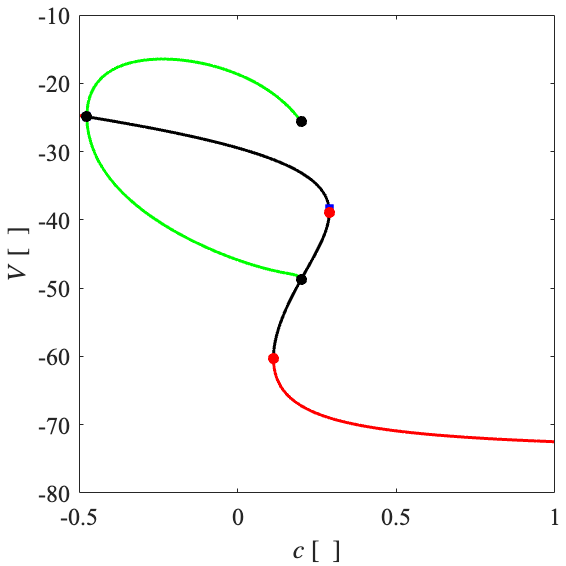

% VISUALIZATION
fig = figure();

Func_VisualizeDiagram(M,AR.BD1_c)
Func_VisualizeLabPoints(M,AR.BD1_c)

xlim([-0.5   1]), xlabel('$c$ [\ ]','interpreter','latex')
ylim([-80  -10]), ylabel('$V$ [\ ]','interpreter','latex')

Func_FigStyle(fig)

## AVERAGING

To apply averaging to our diagram, we have to write a costum function which computes the average variation of `c` on every exported periodic orbit solution of the fast subsystem. In the following, we present the function used to apply averaging theory. After the next chunk of code, the special trajectories are explained in more detail.

This functions takes as input, the model `M`, the `TRJ` structure retrieved through the function *Func_GetTRJ*, and finally the `kpmca` parameter. In the `FUNCTIONs` section, we define those functions required to perform averaging. Note that, we use the parameters stored in the model structure `M` (despite `kpmca`). Now, before moving on, we present the TRJ structure and how to retrieve it. First of all, to get the TRJ structure, we have to use the function *Func_GetTRJ*. This accepts as input the model `M` and the BD structure. Specifically, it automatically enters in all the labelled points stored in the LABPTs field and look whether it is available or not the field "`PO`" (Periodic Orbit). If the field is detected, the routine creates a subfield `TRJi` where saves the periodic orbit (`PO`), the name of the current investigated labelled point (`PTi`) and the vector of parameters (`P`). Schematically, the subfields of these `TRJi` are,

- `PO`: It stands for periodic orbit and it is a structure. It's fields are the period-normalized time `t` and the model's dynamical variables. Keep in mind that, `t` is a vector of values between 0 and 1.

- `P`: It stands for parameters and it stores the combination of hot parameters used to calculate the trajectory. This field presents an additional subfield that is the period of the orbit (`T`).

- `PTi`: It stores the name of the field corresponding to the labelled point from which the `PO` is extracted.

After the FUNCTION section, the INITIALIZATION section takes place and then AVERAGING is applied. Note that, the averaging consists in a set of operations which are applied to every cycle of the computed BD. Finally, in the `EXTRACTION` section, we extract the name of the labelled point to which corresponds the special trajectory which has the average variation closer to 0.

% TRAJECTORIEs
TRJ = Func_GetTRJ(M,AR.BD1_c);

% AVERAGING
[c1,J1,BZ1] = Func_Averaging(M,TRJ,0.18);
[c2,J2,BZ2] = Func_Averaging(M,TRJ,0.25);

## VISUALIZATION: Type 1

There are different method to visualize the results at this point. In this section, we create a figure with four tiles where the different bifurcation diagrams and the average intracellular calcium variation over a cycle are visualized.

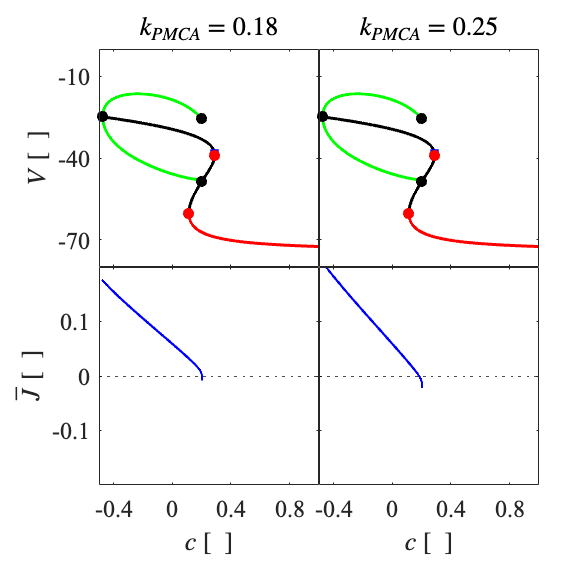

% VISUALIZATION
fig = figure();

tiledlayout(2,2,'TileSpacing','tight','Padding','compact')

nexttile(1)
Func_VisualizeDiagram(M,AR.BD1_c)
Func_VisualizeLabPoints(M,AR.BD1_c)

xlim([-0.5 1]), xticks([-0.4 0 0.4 0.8]), xticklabels({})
ylim([-80  0]), ylabel('$V$ [\ ]','interpreter','latex')
                yticks([-70 -40 -10]), yticklabels({'-70','-40','-10'})
                title('$k_{PMCA} = 0.18$','interpreter','latex')

nexttile(3)

plot(c1,J1,'Color','b','LineWidth',1.2)
yline(0,'LineStyle',':','Color','k')

xlim([-0.5    1]), xticks([-0.4 0 0.4 0.8]), xticklabels({'-0.4','0','0.4','0.8'})
                   xlabel('$c$ [\ ]','interpreter','latex')
ylim([-0.2  0.2]), ylabel('$\bar{J}$ [\ ]','interpreter','latex')
                   yticks([-0.1 0 0.1]), yticklabels({'-0.1','0','0.1'})

nexttile(2)
Func_VisualizeDiagram(M,AR.BD1_c)
Func_VisualizeLabPoints(M,AR.BD1_c)

xlim([-0.5 1]), xticks([-0.4 0 0.4 0.8]), xticklabels({})
ylim([-80  0]), yticks([-70 -40 -10]), yticklabels({})
                title('$k_{PMCA} = 0.25$','interpreter','latex')

nexttile(4)

plot(c2,J2,'Color','b','LineWidth',1.2)
yline(0,'LineStyle',':','Color','k')

xlim([-0.5    1]), xticks([-0.4 0 0.4 0.8]), xticklabels({'-0.4','0','0.4','0.8'})
                   xlabel('$c$ [\ ]','interpreter','latex')
ylim([-0.2  0.2]), yticks([-0.1 0 0.1]), yticklabels({})

Func_FigStyle(fig)

## VISUALIZATION: Type 2

Despite the previous one, the next type of visualization shows the avearging results directly over the bifurcation diagram. We propose the next different type of visualization in order to illustrate the flexibility of this toolbox.

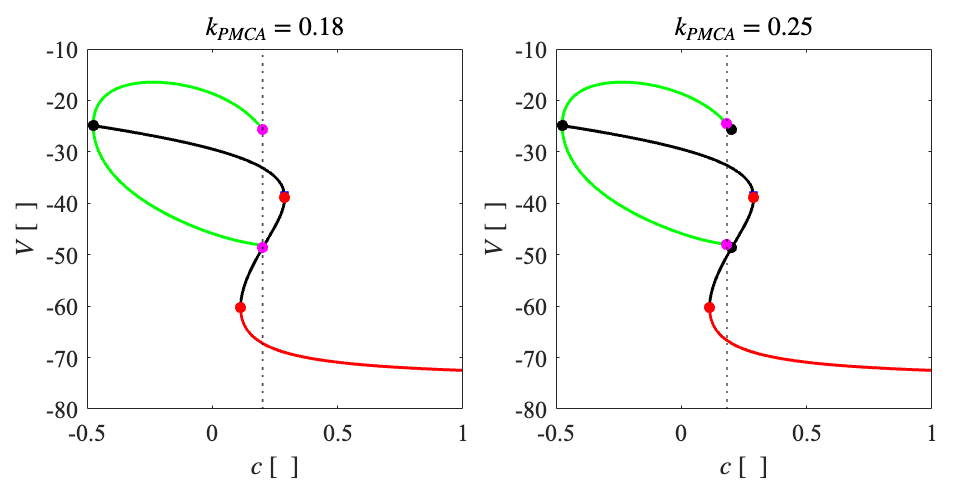

% VISUALIZATION
fig = figure();

tiledlayout(1,2,'TileSpacing','Compact','Padding','Compact')

nexttile()
Func_VisualizeDiagram(M,AR.BD1_c)
Func_VisualizeLabPoints(M,AR.BD1_c)

hold on
plot(AR.BD1_c.LABPTs.(BZ1).c,AR.BD1_c.LABPTs.(BZ1).vU,'Color','m','Marker','o','MarkerFaceColor','m','MarkerSize',5)
plot(AR.BD1_c.LABPTs.(BZ1).c,AR.BD1_c.LABPTs.(BZ1).vL,'Color','m','Marker','o','MarkerFaceColor','m','MarkerSize',5)
hold off

xline(AR.BD1_c.LABPTs.(BZ1).c,'LineStyle',':','Color','k','LineWidth',0.8)

xlim([-0.5   1]), xlabel('$c$ [\ ]','interpreter','latex')
ylim([-80  -10]), ylabel('$V$ [\ ]','interpreter','latex')
                  title('$k_{PMCA} = 0.18$','interpreter','latex')

nexttile()
Func_VisualizeDiagram(M,AR.BD1_c)
Func_VisualizeLabPoints(M,AR.BD1_c)

hold on
plot(AR.BD1_c.LABPTs.(BZ2).c,AR.BD1_c.LABPTs.(BZ2).vU,'Color','m','Marker','o','MarkerFaceColor','m','MarkerSize',5)
plot(AR.BD1_c.LABPTs.(BZ2).c,AR.BD1_c.LABPTs.(BZ2).vL,'Color','m','Marker','o','MarkerFaceColor','m','MarkerSize',5)
hold off

xline(AR.BD1_c.LABPTs.(BZ2).c,'LineStyle',':','Color','k','LineWidth',0.8)

xlim([-0.5   1]), xlabel('$c$ [\ ]','interpreter','latex')
ylim([-80  -10]), ylabel('$V$ [\ ]','interpreter','latex')
                  title('$k_{PMCA} = 0.25$','interpreter','latex')

Func_FigStyle(fig,'OPTIONs',opts)